
% Exercise 1.

N = 10;

x = randn([1 N]);
y = randn([1 N]);

vector1 = x;
vector2 = y;

     
x_i = (vector1-mean(vector1))/std(vector1);
y_i = (vector2-mean(vector2))/std(vector2);
    
r = sum(x_i.*y_i)/N;

disp(sprintf("Calculated correlation coefficient is %.4g",r));

Calculated correlation coefficient is 0.2948


disp(sprintf("Inbounded function correlation coefficient is %.4g",corr(x(:),y(:))));

Inbounded function correlation coefficient is 0.3275


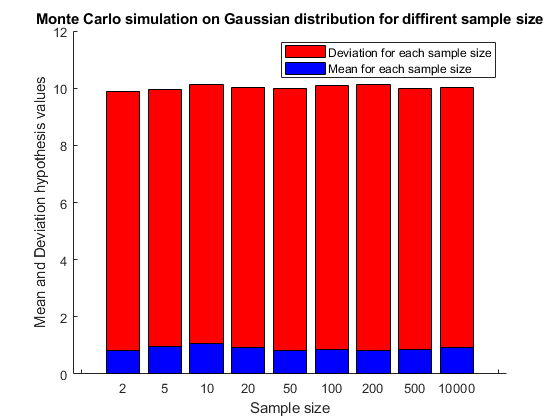

% Exercise 2.

sample_sizes = [2 5 10 20 50 100 200 500 10000];
iteration = 100;

results = zeros(9,2);

%results = zeros(size(sample_sizes(:)),iteration)
index = 1;
for r = sample_sizes
    
    [mean_mean, std_std] = monte_carlo(5,iteration);
 
    
    results(index,:) = [mean_mean std_std];
    index = index +1;
    
end


% visualize the data

names = {'','2', '5' ,'10' ,'20','50' ,'100', '200' ,'500', '10000'};

figure; hold on;
h1 = bar(results(:,1), 'r');
h2 = bar(results(:,2), 'b');
legend([h1 h2], 'Deviation for each sample size', 'Mean for each sample size');
title("Monte Carlo simulation on Gaussian distribution for diffirent sample size")
set(gca,'xticklabel',names);
xlabel('Sample size');
ylabel('Mean and Deviation hypothesis values');

Here we can see that both deviation and mean are the same for different Monte Carlo simulation -> the distribution is normal

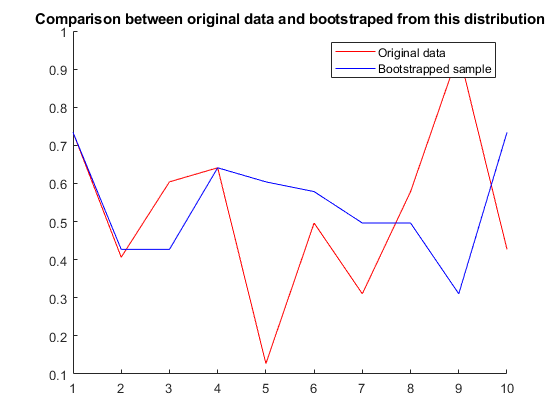

% Exercise 3

x = rand(1,10);


bootstrapped = bootstrap(x);

% visualize the original sample and bootstraped

figure; hold on;
h1 = plot(x,'r');
h2 = plot(bootstrapped,'b');
title('Comparison between original data and bootstraped from this distribution')
legend([h1 h2], 'Original data', 'Bootstrapped sample');

Good point to note that bootstrapped sample can vary intensively

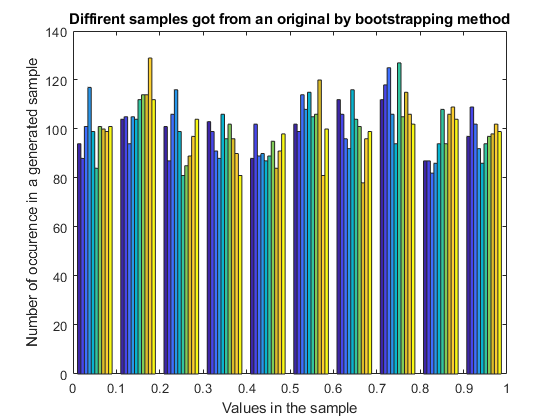

% Exercise 4

bootstrapped_array = ex4_return_2d(1000,10);

% Visualize diffirent samples
% 
figure;
hist(bootstrapped_array');
title('Diffirent samples got from an original by bootstrapping method');
xlabel('Values in the sample');
ylabel('Number of occurence in a generated sample')

Amount of occurencies in different steps for bootstrap method is quite the same.

And if a statistic is stable and is obserabily frequiently, so we suppose the method is reliable and the hypothesis is true

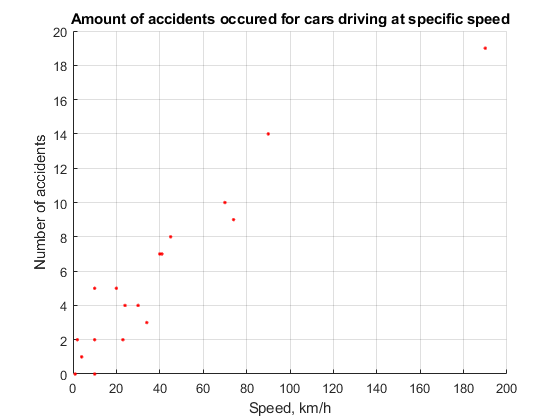

% Exercise 5

% X is for the speed of cars 
x = [10 20 30 23 10 190 45 34 23 1 10 90 40 70 24 41 4 74 2 4]';

% Y is for the amount of accident for cars at specific speed
y = [ 2 5 4 2 5 19 8 3 2 0 0 14 7 10 4 7 1 9 2 1]';

%Visualize the dependency
figure;
scatter(x,y,'r.');
title('Amount of accidents occured for cars driving at specific speed');
grid;
xlabel('Speed, km/h');
ylabel('Number of accidents');

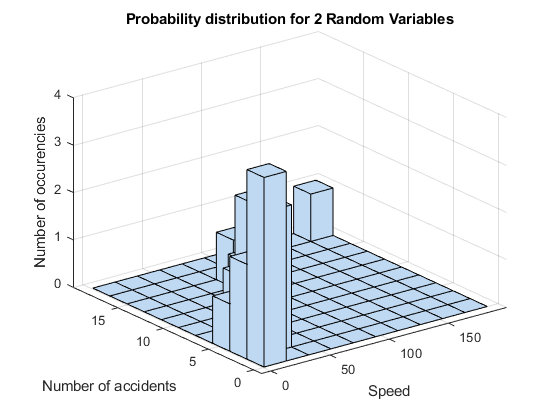



% Plot  2D histogram. On x-axis - values from the first distribution. On
% y-axis - values from the second distribution. On z-axis amount of values
% took specific value.
figure;
hist3([x y],[10, 10]);
title("Probability distribution for 2 Random Variables");
xlabel('Speed');
ylabel('Number of accidents');
zlabel('Number of occurencies');

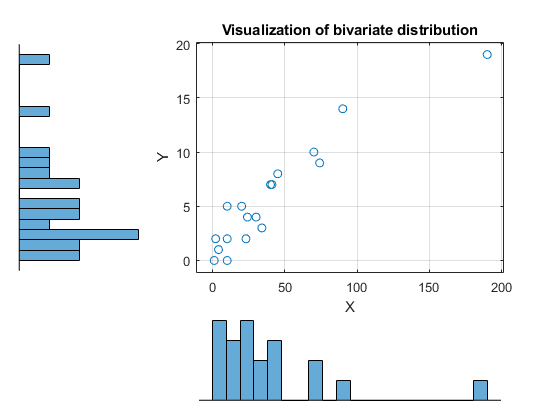

% Calculate marginal probability for X (stands for speed)

scatterhist(x,y,20);grid;
title('Visualization of bivariate distribution');
xlabel('X')
ylabel('Y')

% use filter to sort out unnesessary dots for X variable

x_filter_lower = 100;
x_filter_higher = 200;

% Apply a filter on the X
x_i = x( x_filter_lower<x .* (x<=x_filter_higher));

number_of_occurencies = length(x_i);

% What we got:
% N(0<x<=50) = 16
% N(50<x<100) = 3
% N(100<x<200) = 1

% use filter to sort out unnesessary dots for Y variable

y_filter_lower = 15;
y_filter_higher = 20;

% Apply a filter on the Y
y_i = y( y_filter_lower<y .* (y<=y_filter_higher));

number_of_occurencies = length(y_i);
% What we got:
% N(0<y<=5) = 11
% N(5<y<10) = 5
% N(10<y<15) = 1
% N(15<y<20) = 1


% Finally, we got the matrix with occurancies for X and Y.
% Given that we can calculate the total lenght of samples, we are able to
% calculate the frequency of each random variables separately 

N = length(x);


occurencies_x = [16 3 1] ./N

occurencies_x =     0.8000    0.1500    0.0500


occurencies_y = [11 5 1 1] ./N

occurencies_y =     0.5500    0.2500    0.0500    0.0500




% This is marginal distribution for P(x) and P(y) respectively
% Obviously, the data can be presented in the following table

% N     x     |P(0<x<=50|y)|P(50<x<100|y)|P(100<x<200|y)  |P(Y)   |
% P(0<y<=5|x) |            |             |                |55%    |
% P(5<y<10|x) |            |             |                |25%    |
% P(10<y<15|x)|            |             |                |5%     |
% P(15<y<20|x)|            |             |                |5%     |
% P(X)        |80%         |15%          |5%              |100%   |

% Since we expect the variables are independent, then the joint probability
% P(XY) = P(X)*P(Y), where P(X),P(Y) - marginal distribution for X,Y in
% probability space.

joint_probability_matrix = occurencies_x' * occurencies_y

joint_probability_matrix =     0.4400    0.2000    0.0400    0.0400
    0.0825    0.0375    0.0075    0.0075
    0.0275    0.0125    0.0025    0.0025


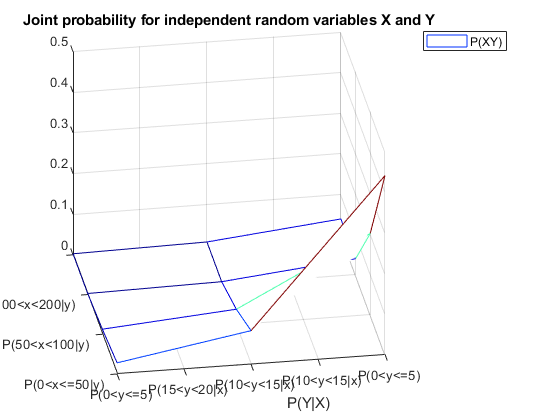

x_names = {'P(0<x<=50|y)'; 'P(50<x<100|y)'; 'P(100<x<200|y)';''};
y_names = {'P(0<y<=5)'; 'P(10<y<15|x)'; 'P(10<y<15|x)';'P(15<y<20|x)'};

s = mesh(joint_probability_matrix);
colormap(jet)
set(gca,'xticklabel',x_names);
set(gca,'yticklabel',y_names);
legend(s,'P(XY)');
title("Joint probability for independent random variables X and Y");
xlabel("P(X|Y)")
ylabel("P(Y|X)")

The Joint probability shows the frequency of one kind of events with respect to the other event's appearance. We supposed the probability of a specific speed of a car is independent from the probability of a specific car accident number.

And having the distribution graph, we can answer for questions like "On what speed were the most accident cars?". In this case, the joint probability distribution shows that drives trends to not run on a high speed, so the number of accident is low.